clear;
plotting = 1; % 1 for plot, 0 for no plot

Load the Files

% Base file path
basePath = 'C:\Users\xiaom\Desktop\LabCourseLab1\LabCourseLab1\Data\';

% Loop over each file
for i = 1:5
    % Generate file name
    fileName = sprintf('F%d.txt', i);
    filePath = fullfile(basePath, fileName);

    % Read the data, skipping the header
    data = readmatrix(filePath, 'NumHeaderLines', 22); 

    % Add offset to all data columns so that each column starts from zero
    offsetData = data - data(1, :);
    laser_init = mean(data(1:5,5));

    % Directly assign columns to the final variable names, using offset data
    eval(sprintf('F%d_time = offsetData(:, 2);', i));
    eval(sprintf('F%d_force = offsetData(:, 3);', i));
    eval(sprintf('F%d_disp = offsetData(:, 5)./laser_init;', i));

    % Analyze the 6th column to decide on naming for axial and lateral, using offset data
    if mean(diff(offsetData(1:200, 6))) > 0
        eval(sprintf('F%d_axial = offsetData(:, 6);', i));
        eval(sprintf('F%d_lateral = offsetData(:, 7);', i));
    else
        eval(sprintf('F%d_axial = offsetData(:, 7);', i));
        eval(sprintf('F%d_lateral = offsetData(:, 6);', i));
    end
end

Select the Unloading Region

%F1: 185->240
%F2: 96->117
%F3: 138->174
%F4: 219->264
%F5: 155->193
% Reason of choise: with 5~10 point offset into the unloading region to
% prevent unstable data points due to the suddent status change of the MTS
% machine.

% Specific index ranges for each file
indexRanges = { ...
    [185, 240], ... % F1
    [96, 117], ...  % F2
    [138, 174], ... % F3
    [219, 264], ... % F4
    [155, 193] ...  % F5
};

% Loop over each file
for i = 1:5
    % Extract start and end indices from the specified ranges
    startIndex = indexRanges{i}(1);
    endIndex = indexRanges{i}(2);

    % Use the start and end indices to extract _unload data for all variables
    eval(sprintf('F%d_force_unload = F%d_force(startIndex:endIndex);', i, i));
    eval(sprintf('F%d_time_unload = F%d_time(startIndex:endIndex);', i, i));
    eval(sprintf('F%d_disp_unload = F%d_disp(startIndex:endIndex);', i, i));
    eval(sprintf('F%d_axial_unload = F%d_axial(startIndex:endIndex);', i, i));
    eval(sprintf('F%d_lateral_unload = F%d_lateral(startIndex:endIndex);', i, i));
end

% Cross-sectional areas for each file (in mm^2)
crossSectionAreas = [ ...
    50.8275, ... % F1
    51.1872, ... % F2
    45.8033, ... % F3
    49.6062, ... % F4
    50.6398  ... % F5
];

% Loop over each file
for i = 1:5
    % Access the _unload force data for the current file
    forceUnloadData = eval(sprintf('F%d_force_unload', i));

    % Calculate stress using the provided cross-sectional area (stress = force / area)
    % Note: The unit of stress will be MPa since 1 N/mm^2 = 1 MPa
    stressUnloadData = forceUnloadData / crossSectionAreas(i);

    % Store the calculated stress data in a new variable
    eval(sprintf('F%d_stress_unload = stressUnloadData;', i));
end

Young's Modulus

% Loop over each file
for i = 1:5
    % Access the stress and strain unload data for the current file
    stressUnloadData = eval(sprintf('F%d_stress_unload', i));
    strainUnloadData = eval(sprintf('F%d_axial_unload', i));

    % Fit a line to the stress vs. strain data (linear fit)
    % polyfit returns coefficients for a polynomial p(x) = p1*x + p2
    % For a linear fit, p1 is the slope, which represents Young's Modulus
    p = polyfit(strainUnloadData, stressUnloadData, 1); % 1 denotes linear fitting

    % The first coefficient is the slope, representing Young's Modulus
    youngsModulus = p(1); % In MPa, since stress is in MPa and strain is dimensionless

    youngsModulus = youngsModulus./1000;

    % Store the calculated Young's Modulus in a new variable
    eval(sprintf('F%d_YoungsModulus = youngsModulus;', i));

    % Optionally, display the Young's Modulus
    fprintf("F%d Young's Modulus: %.2f GPa\n", i, youngsModulus);
end

F1 Young's Modulus: 64.56 GPa
F2 Young's Modulus: 63.31 GPa
F3 Young's Modulus: 199.20 GPa
F4 Young's Modulus: 208.58 GPa
F5 Young's Modulus: 152.04 GPa


Poisson's Ratio Way 1 (Using Unloading Portion)

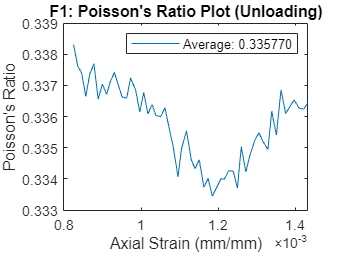

F1 Poisson's Ratio: 0.3358


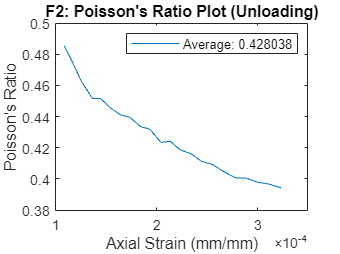

F2 Poisson's Ratio: 0.4280


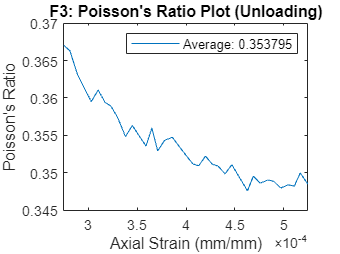

F3 Poisson's Ratio: 0.3538


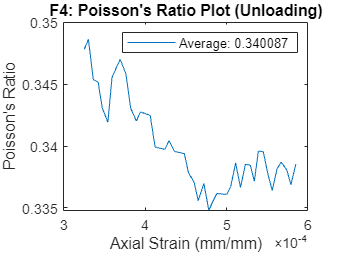

F4 Poisson's Ratio: 0.3401


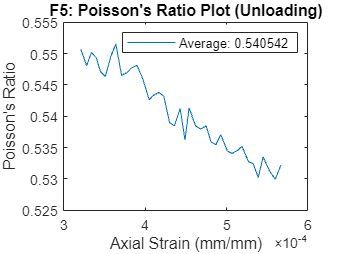

F5 Poisson's Ratio: 0.5405


% Loop over each file
for i = 1:5
    % Access the axial and lateral unload data for the current file
    axialUnloadData = eval(sprintf('F%d_axial_unload', i));
    lateralUnloadData = eval(sprintf('F%d_lateral_unload', i));

    poissonsRatio = -lateralUnloadData ./ axialUnloadData;

    poissonsRatio_mean = mean(poissonsRatio);

    figure;
    plot(axialUnloadData, poissonsRatio)
    hold on
    xlabel("Axial Strain (mm/mm)")
    ylabel("Poisson's Ratio")
    title(sprintf("F%d: Poisson's Ratio Plot (Unloading)", i))
    legend(sprintf("Average: %f", poissonsRatio_mean));
    hold off

    % Display the Poisson's ratio
    fprintf("F%d Poisson's Ratio: %.4f\n", i, poissonsRatio_mean);
end

Poisson's Ratio Way 2 (Using More Data Points) ***(INACURATE ABANDON)***

% Define index ranges for slicing the data
indexRanges = [ ...
    10, 350; ... % Range for F1
    10, 250; ... % Range for F2
    10, 250; ... % Range for F3
    10, 450; ... % Range for F4
    10, 450  ... % Range for F5
];

% Loop over each file
for i = 1:5
    % Access the axial and lateral data for the current file within the specified index range
    axialData = eval(sprintf('F%d_axial(%d:%d)', i, indexRanges(i, 1), indexRanges(i, 2)));
    lateralData = eval(sprintf('F%d_lateral(%d:%d)', i, indexRanges(i, 1), indexRanges(i, 2)));

    % Calculate the Poisson's ratio
    %poissonsRatio = -lateralData ./ axialData;

    %figure;
    %plot(poissonsRatio)
    %poissonsRatio_mean = mean(poissonsRatio);

    % Display the Poisson's ratio
    %fprintf("F%d Poisson's Ratio: %.4f\n", i, poissonsRatio_mean);
end

Yield Stress

% Loop over each file
for i = 1:5
    % Access the force data for the current file
    forceData = eval(sprintf('F%d_force', i));

    % Calculate the stress for each data point (Stress = Force / Area)
    % Convert area from mm^2 to m^2 by dividing by 1e6 for correct units in Pa,
    % then convert stress from Pa to MPa by dividing by 1e6
    stressDataMPa = (forceData / (crossSectionAreas(i) / 1e6)) / 1e6; % Stress in Megapascals (MPa)

    % Store the calculated stress data in a new variable
    eval(sprintf('F%d_stress = stressDataMPa;', i));
end

%F1_stress = F1_stress - 3;

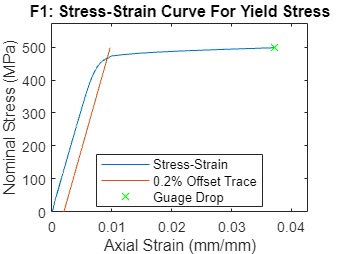

F1: Yield Stress of 465.75 MPa


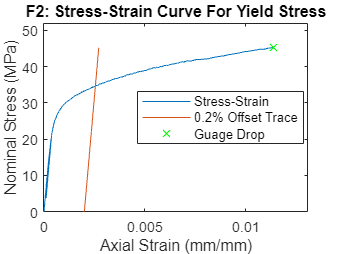

F2: Yield Stress of 34.73 MPa


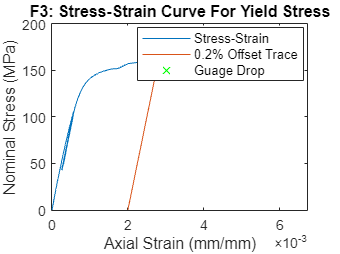

F3: Yield Stress of 161.50 MPa


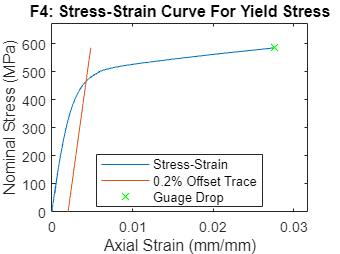

F4: Yield Stress of 467.61 MPa


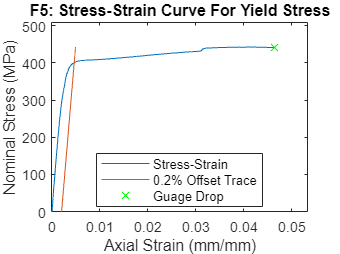

F5: Yield Stress of 401.95 MPa


% Define the range for each dataset
idx_rg_all = [1, 831; 1, 362; 1, 280; 1, 598; 1, 631];  % Assuming same range for simplicity; adjust if necessary

for i = 1:5
    % Access the relevant data for the current dataset
    axialData = eval(sprintf('F%d_axial', i));
    stressData = eval(sprintf('F%d_stress', i));
    youngsModulus = eval(sprintf('F%d_YoungsModulus', i)) * 1000;  % Convert GPa to MPa

    % Calculate reference strain
    refStrain = stressData / youngsModulus;

    % Define the range for the current dataset
    idx_rg = idx_rg_all(i, :);
    
    if (plotting == 1)
        % Plot the stress-strain curve
        figure;  % Create a new figure for each dataset
        plot(axialData(idx_rg(1):idx_rg(2)), stressData(idx_rg(1):idx_rg(2)));
        hold on;
        plot(refStrain(idx_rg(1):idx_rg(2)) + 0.002, stressData(idx_rg(1):idx_rg(2)));  % 0.2% Offset line
        plot(max(axialData(idx_rg(1):idx_rg(2))), max(stressData(idx_rg(1):idx_rg(2))), 'x', 'Color','green')
        xlim([0 max(eval(sprintf('F%d_axial(idx_rg(1):idx_rg(2))', i)))*1.15]);
        ylim([0 max(eval(sprintf('F%d_stress(idx_rg(1):idx_rg(2))', i)))*1.15])
        xlabel("Axial Strain (mm/mm)");
        ylabel("Nominal Stress (MPa)");
        title(sprintf("F%d: Stress-Strain Curve For Yield Stress", i));
        legend("Stress-Strain", "0.2% Offset Trace", "Guage Drop", "Location", "best");
        hold off;
    end

    % Find the first occurrence where the difference in axial strain exceeds 0.002
    tolerance = 0.002;  % 0.2% Offset
    validIndices = find(axialData - (refStrain) > tolerance, 1);

    if isempty(validIndices)
        disp(sprintf('F%d: No matching stress values found with axial strain over 0.002', i));
    else
        % Corresponding stress value
        matchingStress = stressData(validIndices);

        %fprintf('F%d: At index %d with a Yield Stress of %.2f MPa\n', i, validIndices, matchingStress);
        fprintf('F%d: Yield Stress of %.2f MPa\n', i, matchingStress);
    end
end

Stress-Strain Curve

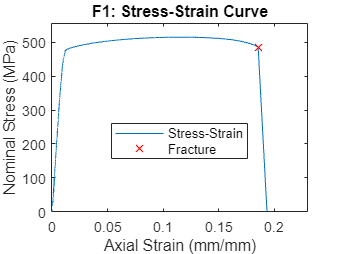

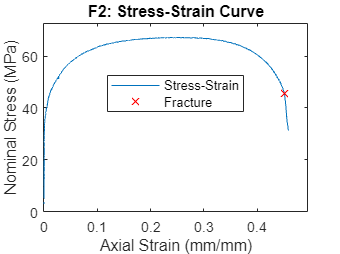

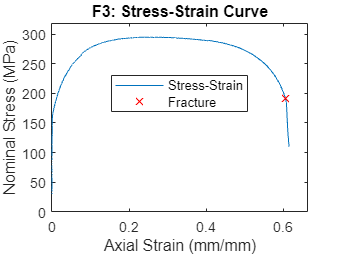

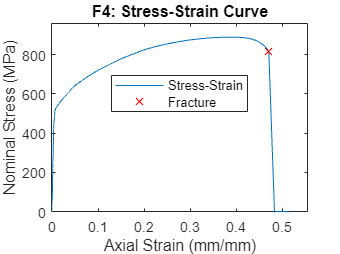

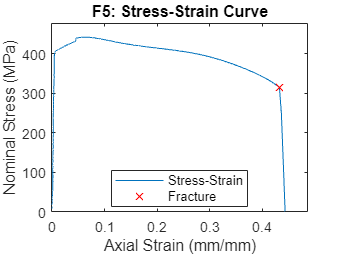

% Define the range for each dataset
idx_rg_frac = [1, 1101; 1, 882; 1, 885; 1, 1003; 1, 853];  % Assuming same range for simplicity; adjust if necessary
idx_rg_all = [idx_rg_frac(:,1) idx_rg_frac(:,2) + 3];

for i = 1:5

    % Access the relevant data for the current dataset
    axialData = eval(sprintf('F%d_disp', i));
    stressData = eval(sprintf('F%d_stress', i));
    youngsModulus = eval(sprintf('F%d_YoungsModulus', i)) * 1000;  % Convert GPa to MPa

    % Define the range for the current dataset
    idx_rg = idx_rg_all(i, :);
    idx_rg_f = idx_rg_frac(i, :);
    
    if (plotting == 1)
        % Plot the stress-strain curve
        figure;  % Create a new figure for each dataset
        plot(axialData(idx_rg(1):idx_rg(2)), stressData(idx_rg(1):idx_rg(2)));
        hold on;
        plot(max(axialData(idx_rg_f(1):idx_rg_f(2))), stressData(idx_rg_f(2)), 'x', 'Color','red')
        xlim([0 max(eval(sprintf('F%d_disp(idx_rg(1):idx_rg(2))', i)))*1.08]);
        ylim([0 max(eval(sprintf('F%d_stress(idx_rg(1):idx_rg(2))', i)))*1.08])
        xlabel("Axial Strain (mm/mm)");
        ylabel("Nominal Stress (MPa)");
        title(sprintf("F%d: Stress-Strain Curve", i));
        legend("Stress-Strain", "Fracture", "Location", "best");
        hold off;
    end
end

Ultimate Tensile Strength

% Loop over each file
for i = 1:5
    % Access the force data for the current file
    stressData = eval(sprintf('F%d_stress', i));
    
    UTS = max(stressData);

    % Display the Ultimate Tensile Stress
    fprintf("F%d Ultimate Tensile Stress: %.2f MPa\n", i, UTS);
end

F1 Ultimate Tensile Stress: 515.29 MPa
F2 Ultimate Tensile Stress: 67.32 MPa
F3 Ultimate Tensile Stress: 295.00 MPa
F4 Ultimate Tensile Stress: 889.03 MPa
F5 Ultimate Tensile Stress: 442.75 MPa
